# ECOM062 - Robótica - Cinemática RoArm-M2

`Universidade Federal de Alagoas - UFAL`

`Instituto de Computação - IC`

`Prof. Glauber R. Leite (glauber@ic.ufal.br)`

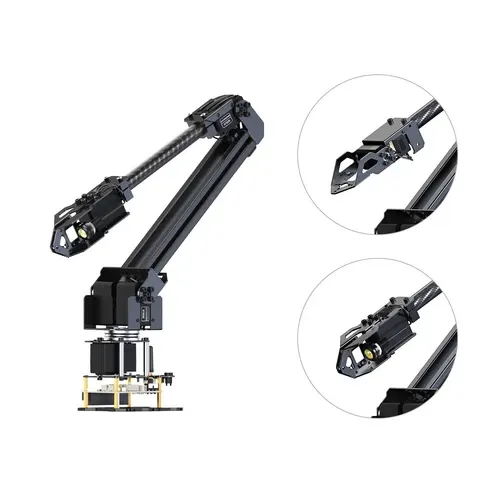

## `Comunicação e mapeamento`

`Estamos usando comunicação serial via USB`

s = serialport("/dev/tty.usbserial-10",115200)

s =   Serialport with properties:

                 Port: "/dev/tty.usbserial-10"
             BaudRate: 115200
                  Tag: ""
    NumBytesAvailable: 0

  Show all properties, functions


setDTR(s, false)
setRTS(s, false)

Podemos mandar um comando simples (inicialização do robô em uma determinada configuração) usando um payload em json

s.writeline(['{"T":102,"base":', num2str(0) ,',"shoulder":', num2str(0), ',"elbow":', num2str(pi/2), ',"hand":', num2str(pi),',"spd":0,"acc":10}'])

Fiz uma concatenação para mandar o seguinte vetor: $\left\lbrack \;0,0,\frac{\pi }{2},\pi \right\rbrack$. Vimos, durante a aula que esse é o vetor que vamos definir como "home" do robô. Então precisamos montar uma função de mapeamento $h:{\mathbb{R}}^{\mathrm{dof}} \to {\mathbb{R}}^{\mathrm{dof}}$ que damos como entrada o valor matematicamente compatível com nossa modelagem ($q$) e retornamos o vetor $q^{\prime }$ que gera a atuação desejada nos motores. Para isso, vamos usar a seguinte função:

h = @(q) [q(1), q(2), q(3)+pi/2, q(4)+pi]

h = function_handle with value:
    @(q)[q(1),q(2),q(3)+pi/2,q(4)+pi]


Agora, $q=\left\lbrack 0,0,0,0\right\rbrack$ é nosso *home* que é traduzido para $h\left(q\right)=\left\lbrack 0,0,\frac{\pi }{2},\pi \right\rbrack$ para a atuação dos motores.

## Cinemática direta

### Parâmetros DH

Usando a notação padrão de Denavit-Hartenberg, montamos a seguinte tabela

dh_params = [0, 0.12606, 0, -pi/2;
            -pi/2, 0, 0.23682, 0;
            pi/2, 0, 0.03, 0;
            0, 0, 0.215, pi/2;
            0, 0, 0.06515, 0
           ];

dh_matrix = @(theta, d, a, alpha) ...
    [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
    sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
    0, sin(alpha), cos(alpha), d;
    0, 0, 0, 1];

T_0_1 = dh_matrix(dh_params(1, 1), dh_params(1, 2), dh_params(1, 3), dh_params(1, 4));
T_1_2 = dh_matrix(dh_params(2, 1), dh_params(2, 2), dh_params(2, 3), dh_params(2, 4));
T_2_v1 = dh_matrix(dh_params(3, 1), dh_params(3, 2), dh_params(3, 3), dh_params(3, 4));
T_v1_3 = dh_matrix(dh_params(4, 1), dh_params(4, 2), dh_params(4, 3), dh_params(4, 4));
T_3_4 = dh_matrix(dh_params(5, 1), dh_params(5, 2), dh_params(5, 3), dh_params(5, 4));

Podemos montar a pose de cinemática direta para o caso em que o vetor é $q=[0,0,0,0]$ com a composição de matrizes.

disp(T_0_1 * T_1_2 * T_2_v1 * T_v1_3 * T_3_4)

    1.0000         0         0    0.3101
         0    1.0000         0   -0.0000
         0         0    1.0000    0.3629
         0         0         0    1.0000



Agora podemos montar uma função de cinemática direta

function T_0_4 = fkine(q)
    % Precisei trazer de volta as definições por conta do escopo da função
    dh_params = [0, 0.12606, 0, -pi/2;
            -pi/2, 0, 0.23682, 0;
            pi/2, 0, 0.03, 0;
            0, 0, 0.215, pi/2;
            0, 0, 0.06515, 0
           ];

    dh_matrix = @(theta, d, a, alpha) ...
        [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
        sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
        0, sin(alpha), cos(alpha), d;
        0, 0, 0, 1];

    T_0_1 = dh_matrix(q(1) + dh_params(1, 1), dh_params(1, 2), dh_params(1, 3), dh_params(1, 4)); % revolute
    T_1_2 = dh_matrix(q(2) + dh_params(2, 1), dh_params(2, 2), dh_params(2, 3), dh_params(2, 4)); % revolute
    T_2_v1 = dh_matrix(dh_params(3, 1), dh_params(3, 2), dh_params(3, 3), dh_params(3, 4)); % fixed
    T_v1_3 = dh_matrix(q(3) + dh_params(4, 1), dh_params(4, 2), dh_params(4, 3), dh_params(4, 4)); % revolute
    T_3_4 = dh_matrix(q(4) + dh_params(5, 1), dh_params(5, 2), dh_params(5, 3), dh_params(5, 4)); % revolute

    T_0_4 = T_0_1 * T_1_2 * T_2_v1 * T_v1_3 * T_3_4;
end

Testando com o vetor $q = \left[\frac{\pi}{4}, -\frac{\pi}{6}, \frac{\pi}{6}, -\frac{\pi}{4}\right]$

q = [pi/4, -pi/6, pi/6, 0]

q =     0.7854   -0.5236    0.5236         0


q_r = h(q)
s.writeline(['{"T":102,"base":', num2str(q_r(1)) ,',"shoulder":', num2str(q_r(2)), ',"elbow":', num2str(q_r(3)), ',"hand":', num2str(q_r(4)),',"spd":0,"acc":10}'])

fkine([pi/4,-pi/6,pi/6,0])

ans =     0.7071   -0.7071    0.0000    0.1327
    0.7071    0.7071   -0.0000    0.1327
   -0.0000    0.0000    1.0000    0.3462
         0         0         0    1.0000


fkine([pi/4,-pi/6,pi/6,-pi/4])

ans =     1.0000   -0.0000    0.0000    0.1518
         0    1.0000   -0.0000    0.0867
   -0.0000   -0.0000    1.0000    0.3462
         0         0         0    1.0000


### Tentando uma abordagem simbólica

Vamos usar variáveis simbólicas para tentar montar a matriz desejada

syms theta_1 theta_2 theta_3 theta_4
fkine([theta_1, theta_2, theta_3, theta_4])

### Modelagem com a Robotics System Toolbox

Usando a MATLAB Robotics System Toolbox, podemos montar o objeto que representa o robô (a ordem que é usada na toolbox é diferente, apesar de ainda ser a notação padrão [a, alpha, d, theta]):

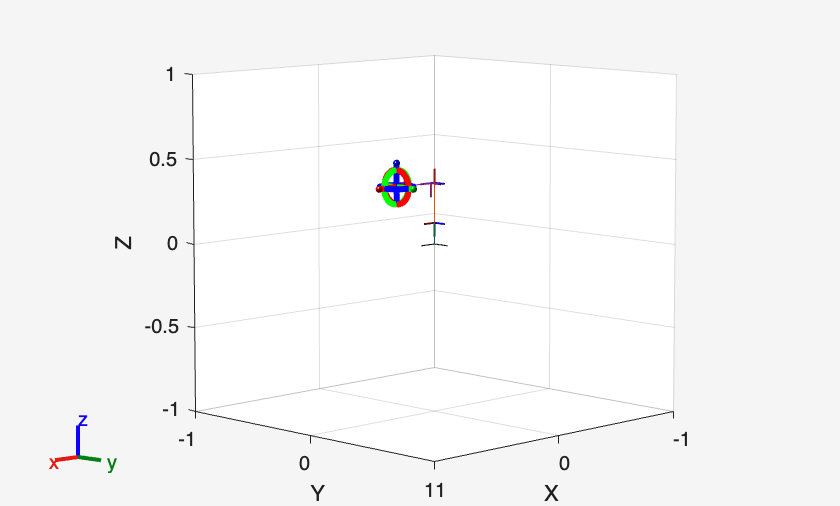

robot = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1, T_0_1);
body1.Joint = jnt1;
addBody(robot, body1, 'base');

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2, T_1_2);
body2.Joint = jnt2;
addBody(robot, body2, 'body1')

bodyv1 = rigidBody('bodyv1');
jntv1 = rigidBodyJoint('jntv1','fixed');
setFixedTransform(jntv1, T_2_v1);
bodyv1.Joint = jntv1;
addBody(robot, bodyv1, 'body2')

body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
setFixedTransform(jnt3, T_v1_3);
body3.Joint = jnt3;
addBody(robot, body3, 'bodyv1')

body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
setFixedTransform(jnt4, T_3_4);
body4.Joint = jnt4;
addBody(robot, body4, 'body3')

figure(Name="Interactive GUI")
gui = interactiveRigidBodyTree(robot,MarkerScaleFactor=0.5);

## Cinemática Inversa

function q = invkine(x, y, z, phi)
% Entradas:
%   x, y, z : Posição desejada do efetor final (em mm ou metros)
%   phi     : Ângulo de rolagem da ferramenta desejado (radianos)
%
% Saída:
%   q       : Vetor linha com as juntas [q1, q2, q3, q4] em radianos.
%             Retorna NaN se a posição for inalcançável.

dh_params = [0, 0.12606, 0, -pi/2;
    -pi/2, 0, 0.23682, 0;
    pi/2, 0, 0.03, 0;
    0, 0, 0.215, pi/2;
    0, 0, 0.06515, 0
    ];

% Para facilitar a referencia
d1 = dh_params(1,2);
a2 = dh_params(2,3);
a_v1 = dh_params(3,3);
a3 = dh_params(4,3);
a4 = dh_params(5,3);

% Replicamos a junta 4
q4 = phi;

% Encontrar q1 (Compensando o arrasto causado por q4 no plano XY)
% Equação base: Y*cos(q1) - X*sin(q1) = -a4*sin(q4)
C1 = -a4 * sin(q4);
r_xy = sqrt(x^2 + y^2);

if abs(C1) > r_xy
    warning('Erro: Posição X, Y inalcançável devido à orientação da ferramenta.');
    q = [NaN, NaN, NaN, NaN];
    return;
end

gamma1 = asin(C1 / r_xy);
q1 = atan2(y, x) - gamma1;

% 4. Reduzir para um problema 2D (Braço Plano)
% Projeta a posição X, Y no plano de ação de q2 e q3
R_plano = x * cos(q1) + y * sin(q1);
Z_comp = z - d1;

% O elo 3 "virtual" se junta ao elo 4 formando um comprimento L
L = a3 + a4 * cos(q4);

% 5. Encontrar q3 usando a distância do centro do pulso
D2 = R_plano^2 + Z_comp^2;

% Equação: A3*sin(q3) + B3*cos(q3) = C3
A3 = -2 * L * a2;
B3 = 2 * L * a_v1;
C3 = D2 - a2^2 - a_v1^2 - L^2;

R3 = sqrt(A3^2 + B3^2);

if abs(C3) > R3
    warning('Erro: Alvo Z, Raio inalcançável (fora da área de alcance principal).');
    q = [NaN, NaN, NaN, NaN];
    return;
end

theta3 = atan2(A3, B3);

% Calculando q3 (O "- asin" pega a configuração padrão. "+ pi + asin" pegaria a outra).
q3 = theta3 - asin(C3 / R3);

% Normaliza o ângulo para ficar entre -pi e pi
q3 = atan2(sin(q3), cos(q3)); 

% 6. Encontrar q2 (Agora que q3 é conhecido, o sistema se torna linear)
M = a2 - L * sin(q3);
N = a_v1 + L * cos(q3);

sin_q2 = M * R_plano - N * Z_comp;
cos_q2 = N * R_plano + M * Z_comp;

q2 = atan2(sin_q2, cos_q2);

% 7. Montar vetor final
q = [q1, q2, q3, q4];
end

q = invkine(0.3101,0,0.3629,0)

q =          0    0.8605   -1.5706         0


q_r = h(q)

q_r =          0    0.8605    0.0002    3.1416
